a = 4; b = 3; c = 4; d = 10;
t_1 = -1; t_2 = 4;
T = 20;
dt = 0.1;

t = -T/2 : dt : T/2;
g = zeros(size(t));

for i=1:length(t)
    if t_1 <= t(i) && t(i) <= t_2
        g(i) = a;
    end
end

u = g + b*(rand(size(t)) - 0.5) + c*sin(d*t);

u_fourier = fftshift(fft(u));

V = 1/dt;
dv = 1/T;
v = round(-V/2 : dv : V/2, 3);

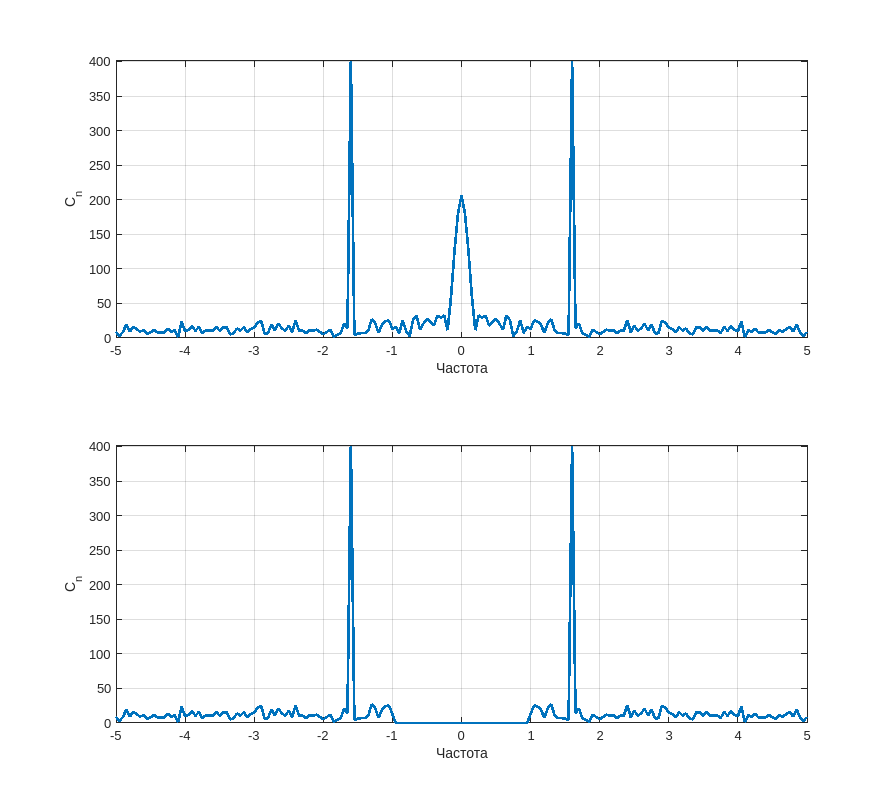

v_0_left = [
    find(v == -5), find(v == 1)
];
v_0_right = [
    find(v == -1), find(v == 5)
];

u_fourier_filtered = zeros(size(u_fourier));
for i=1:length(v_0_right)
    u_fourier_filtered(v_0_left(i):v_0_right(i)) = u_fourier(v_0_left(i):v_0_right(i));
end

figure;
ax_1 = subplot(2, 1, 1);
plot(v, abs(u_fourier), 'LineWidth', 2);
axis(ax_1, 'tight');
grid on;
xlabel("Частота");
ylabel("С_n");

ax_2 = subplot(2, 1, 2);
plot(v, abs(u_fourier_filtered), 'LineWidth', 2);
axis(ax_2, 'tight');
grid on;
xlabel("Частота");
ylabel("С_n");

linkaxes([ax_1, ax_2]);
pos = get(gcf, 'Position');
set(gcf, 'Position', pos + [-1000 -1000 1000 1000]);

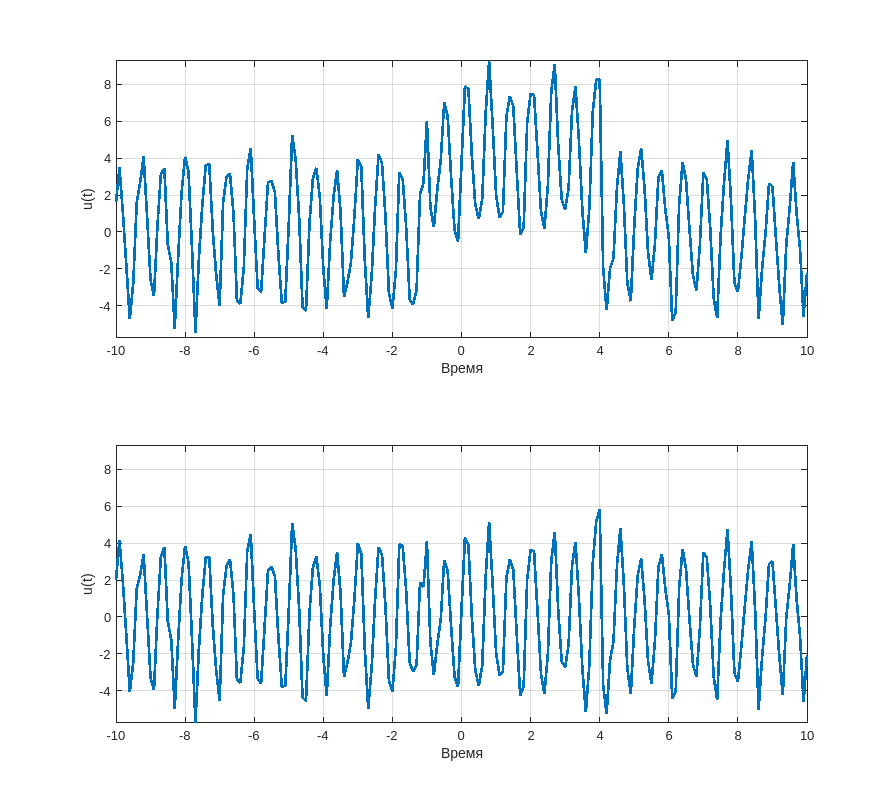

u_filtered = ifft(ifftshift(u_fourier_filtered));

figure;
ax_1 = subplot(2, 1, 1);
plot(t, u, 'LineWidth', 2);
axis(ax_1, 'tight');
grid on;
xlabel("Время");
ylabel("u(t)");

ax_2 = subplot(2, 1, 2);
plot(t, u_filtered, 'LineWidth', 2);
axis(ax_2, 'tight');
grid on;
xlabel("Время");
ylabel("u(t)");

linkaxes([ax_1, ax_2]);
pos = get(gcf, 'Position');
set(gcf, 'Position', pos + [-1000 -1000 1000 1000]);